%CLEAR THE WORKSPACE

clear all;
clc
close all;

%TIME INTERVAL AND INITIAL CONDITIONS

tspan = [0 200];
init_cond = [0.99 .01 0 0 0]';

%.7 high, .5 medium, .3 low... constant low of .22

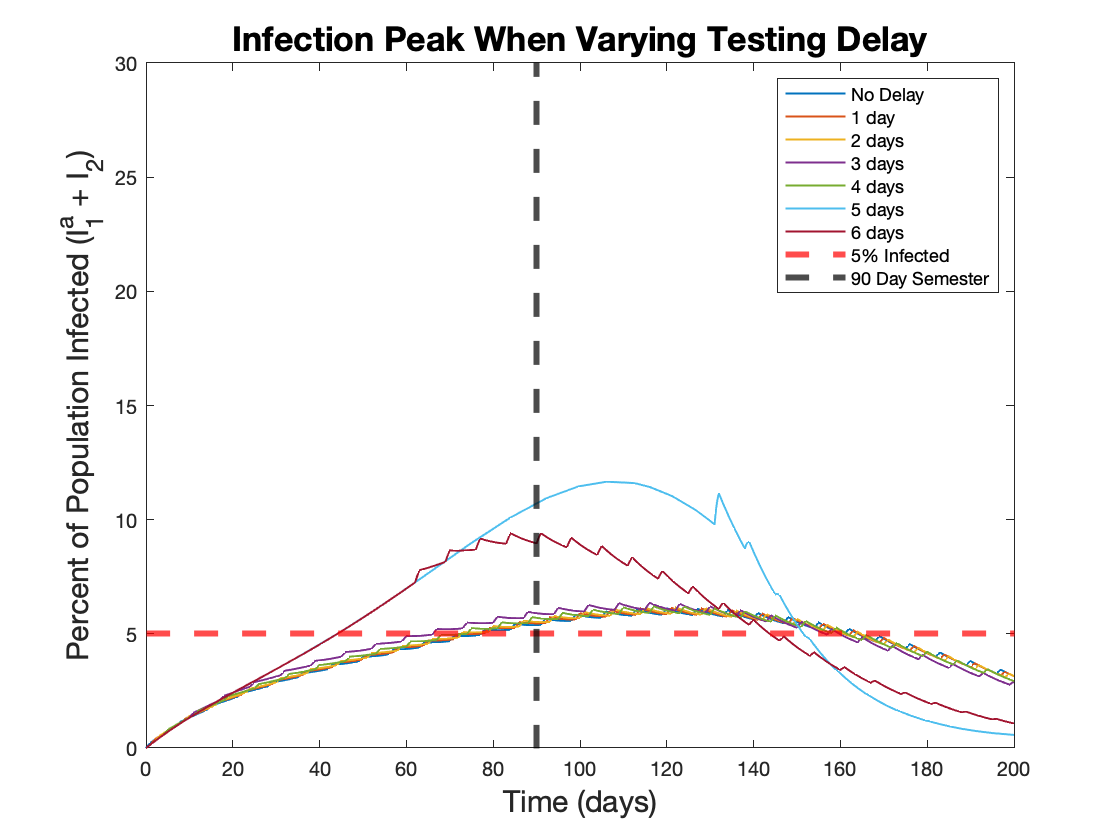

%% VECTOR FOR vr1 = .5 LOW vr OF .22 %%

% Parameter Values

params = [.85, 0.143, 0.06, 0.143, 0.05, 0.05, 0];

% Various Testing Delays

delay_in_testing = 0:1:6;

%Pre Allocate Space for Tc for vr1

for j = 1:length(delay_in_testing)
    
        tR_fun = @(t, S, I1u) pulse_tR_fun(t,S, I1u, .1,7,delay_in_testing(j)); %(t, S, testing rate, days_tested, delay after party)
        
        vR_params = [.22,.3,0,1]; % [vR_low,vR_high,t_on,t_off]

        vR_fun = @(t) pulse_vR_fun(t, vR_params,7,1); %(t,vR_params,party_days,single_event)
        
        [T, S, I1u, I1a, I2, R] = covidsolver(params, tR_fun, vR_fun, init_cond, tspan, 0, 0, 0 ,0);
        
        peak = (I1a + I2)*100;
        
        plot(T, peak, 'linewidth', 1, 'LineStyle',"-")
        
        hold on
        
end


yline(5, 'lineWidth', 3, 'lineStyle', ' --', 'color', 'r')
xline(90, 'lineWidth', 3, 'lineStyle', ' --', 'color', 'black')

legend('No Delay', '1 day', '2 days', '3 days', '4 days', '5 days', '6 days',...
    '5% Infected', '90 Day Semester')

title('Infection Peak When Varying Testing Delay', 'FontSize', 20)
xlabel('Time (days)','FontSize', 17)
ylabel('Percent of Population Infected (I_1^a + I_2)','FontSize', 17)
ylim([0 30])


hold off

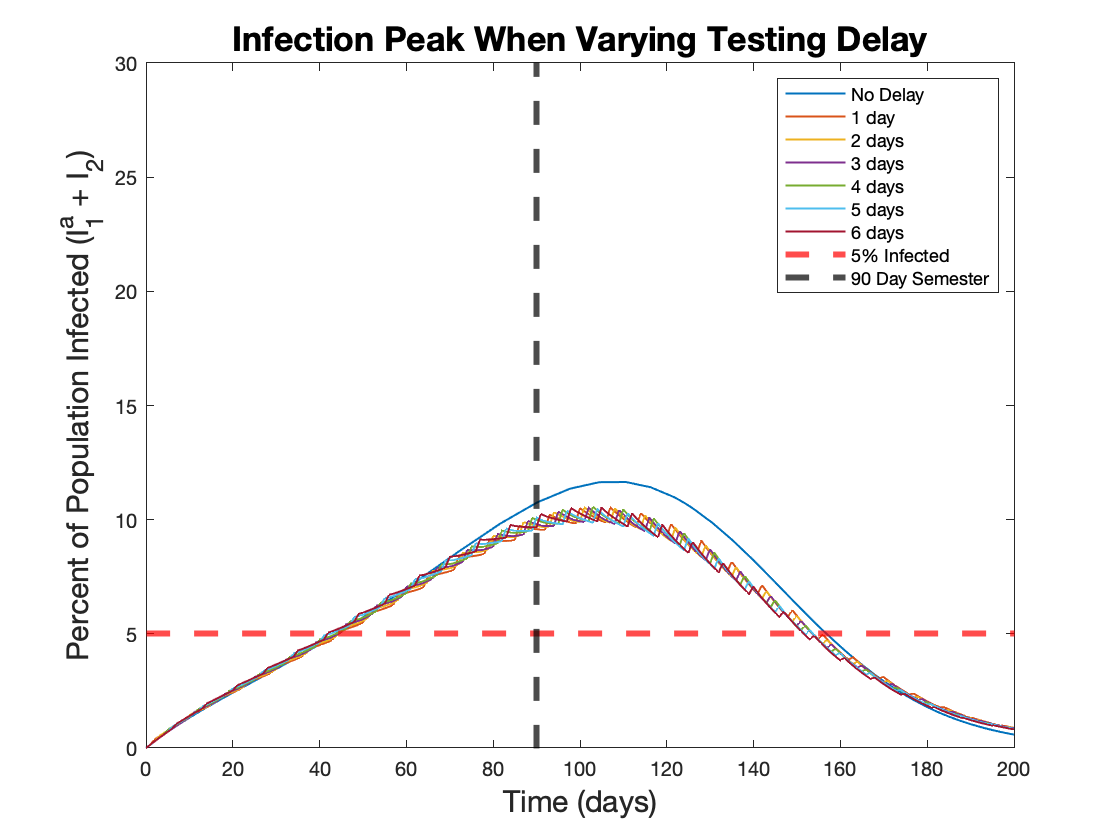

%% VECTOR FOR vr1 = .5 LOW vr OF .22 %%

% Parameter Values

params = [.85, 0.143, 0.06, 0.143, 0.05, 0.05, 0];

% Various Testing Delays

delay_in_testing = [7,1,2,3,4,5,6];

%Pre Allocate Space for Tc for vr1

for j = 1:length(delay_in_testing)
    
        tR_fun = @(t, S, I1u) pulse_tR_fun(t,S, I1u, .1,7,delay_in_testing(j)); %(t, S, testing rate, days_tested, delay after party)
        
        vR_params = [.22,.3,0,1]; % [vR_low,vR_high,t_on,t_off]

        vR_fun = @(t) pulse_vR_fun(t, vR_params,7,0); %(t,vR_params,party_days,single_event)
        
        [T, S, I1u, I1a, I2, R] = covidsolver(params, tR_fun, vR_fun, init_cond, tspan, 0, 0, 0 ,0);
        
        peak = (I1a + I2)*100;
        
        plot(T, peak, 'linewidth', 1, 'LineStyle',"-")
        
        hold on
        
end


yline(5, 'lineWidth', 3, 'lineStyle', ' --', 'color', 'r')
xline(90, 'lineWidth', 3, 'lineStyle', ' --', 'color', 'black')

legend('No Delay', '1 day', '2 days', '3 days', '4 days', '5 days', '6 days',...
    '5% Infected', '90 Day Semester')

title('Infection Peak When Varying Testing Delay', 'FontSize', 20)
xlabel('Time (days)','FontSize', 17)
ylabel('Percent of Population Infected (I_1^a + I_2)','FontSize', 17)
ylim([0 30])

hold off